T = readtable('/Users/ivankcl/Desktop/ASTRI/code/data/calibration.csv.nosync.csv')

T = 7525×35 table
    PacketCounter    SampleTimeFine      Acc_X        Acc_Y      Acc_Z       Gyr_X        Gyr_Y        Gyr_Z       Mag_X       Mag_Y       Mag_Z     VelInc_X     VelInc_Y     VelInc_Z    OriInc_q0    OriInc_q1    OriInc_q2    OriInc_q3     Pressure     Quat_q0    Quat_q1      Quat_q2      Quat_q3      Roll       Pitch         Yaw       Mat_1__1_    Mat_2__1_    Mat_3__1_    Mat_1__2_    Mat_2__2_    Mat_3__2_    Mat_1__3_


Fs = 40;
AccelerationReadings = fillmissing(table2array(T(1:end,3:5)),'previous');
AngularVelocityReadings = fillmissing(table2array(T(1:end,6:8)), 'previous');
MagneticFieldReadings = fillmissing(table2array(T(1:end, 9:11)),'previous');

imuFs = 40;
size(AccelerationReadings)

ans =         7525           3


f = insfilterMARG;
f.IMUSampleRate = imuFs;
% f.ReferenceLocation = [0 0 0];
% f.AccelerometerBiasNoise = 9.61703842e-9;
% f.AccelerometerNoise = 0.000016;
% f.GyroscopeBiasNoise = 3.6e-9;
% f.GyroscopeNoise = 0.00000123456;
% f.MagnetometerBiasNoise = 1e-14;
% f.GeomagneticVectorNoise = 1e-12;
% f.StateCovariance = 1e-9*ones(22);
% 
Rmag = [1e-10,1e-10,1e-10;1e-10,1e-10,1e-10;1e-10,1e-10,1e-10];
% initState = [0.999961;0.008398;-0.002586;-0.000846;0;0;0;0;0;0;1e-5;1e-5;1e-5;1e-5;1e-5;1e-5;1e-12;1e-12;1e-12;1e-10;1e-10;1e-10];
% f.State = initState;
 
gpsidx = 1;
N = size(AccelerationReadings,1);
p = zeros(N,3);
q = zeros(N,1,'quaternion');

for ii = 1:size(AccelerationReadings,1)               % Fuse IMU
  
   f.predict(AccelerationReadings(ii,:), AngularVelocityReadings(ii,:));
        
   if ~mod(ii,fix(imuFs/4))           
       f.fusemag(MagneticFieldReadings(ii,:),Rmag);
   end
%   
 
   [p(ii,:),q(ii)] = pose(f);        %Log estimated pose
   
end

fprintf('done')

done

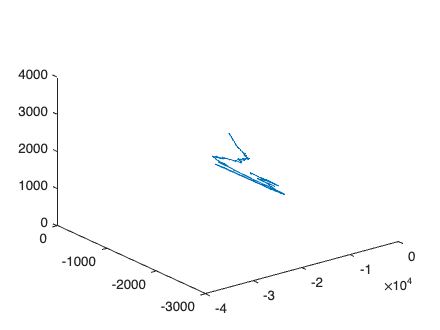

plot3(p(:,1),p(:,2),p(:,3))